# Reservoir Computing for Robotic Control

# Objectives

Reservoir computing is an efficient learning method that experts in emulating dynamical systems. The key idea is to train the readout of a neural network without adjusting the network's input and internal connections. 

This tutorial aims to introduce the concept of reservoir computing, explain the methodology behind its use, and demonstrate its implementation when used for robotic control of a single pendulum. 

The tutorial is structured as follows:

# 1 - Introduction to Robotic Control -

There are a multitude of ways to control a robotic system depending on the characteristics. 

Throughout this tutorial we will use a simple Simulink pendulum to demonstrate our implementation of control. 

$\theta \left(t\right),\dot{\theta} \left(t\right),\theta^* \left(t\right),{\dot{\theta} }^* \left(t\right)\;\mathrm{and}\;\tau \left(t\right)$ represent the pendulum's current angle, current angular velocity, desired angle, desired angular velocity and current torque applied to the joint respectively./

.                       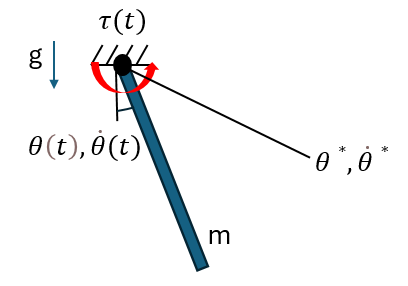

%%%%%%%%%%%%%%%%%%%%%%%%% RUN THIS CODE TO SHOW SAMPLE SIMULINK MODEL    %%%%%%%%%%%%%%%%%%%%%%%%
clear;
clc;
close all;

define_variables();   %this is an external file that sets the values for many of the values within the Simulink mode

robot_ini_theta_p = pi-0.1;
robot_ini_thetadot_p = 0;
dt = 0.01;  %time interval for updating, (increase this number if your computer)

out_simualtion = sim("PID_pendulum", 'StopTime', num2str(simTime));  %run Simulink model of pendulum (free-fall)

**Fully Actuated vs. Underactauted **

A fully actuated system is a mechanical or control system in which the number of independent control inputs (actuators) is equal to the number of degrees of freedom (DOF) of the system. In other words, for every degree of freedom that the system can exhibit, there is a corresponding actuator capable of directly controlling that motion. This ensures that the system can be precisely controlled in all its possible movements

An underactuated system is a mechanical or control system where the number of independent control inputs (actuators) is fewer than the number of degrees of freedom (DOF), or where the actuators are limited in the torque or force they can apply. As a result, underactuated systems are significantly harder to control than fully actuated. 

Underatauted systems require a more thorough understanding of the robot dynamics to order to perform precise control.

# 2 - PID Control of Simple Pendulum

Proportional Intergral Derivative (PID) Control is a common and easy to implement a form of control: 

A simple PID controller can be used to control the angle of a simple single pendulum.

It can be expressed through the equation: 


$$\[
u(t) = K_p \left( r(t) - y(t) \right) + K_i \int_0^t \left( r(\tau) - y(\tau) \right) \, d\tau + K_d \frac{d}{dt} \left( r(t) - y(t) \right)
\]
$$


where: 

- $u\left(t\right)\;$is the control torque

- $r\left(t\right)$ is the desired output 

- $y\left(t\right)$ is the actual output

- $K_p \;$is the proportional gain

- $K_d$ is the derivative gain

- $K_i$ is the integral gain 

The proportional, derivative and integral gain coefficients can be optimised to achieve different control characteristics. 

**PID Control Parameter Comparison (plotting different control coefficients) **

%%%%%% RUN THIS CODE TO PLOT CONTROL OF PENDULUM FOR VARYING PID PARAMETERS %%%%% 

define_variables();   %this is an external file that sets the values for many of the values within the Simulink mode

PID_on = true; %PID_on as false means the pendulum drops freely, PID_on as true mean PID controller tries to control to desired angle
desired_theta = pi;  %the desired angle of the pendulum when using PID controller


%%%%%%Change from singular values to list to iterate over different values %%%%%%%%
Kp_range = [1, 2, 3]; 
Kd_range = [0.1, .5];
Ki_range = 5;
%%%%%%Change from singular values to list to iterate over different values %%%%%%%%

robot_ini_theta_p = 0;
robot_ini_thetadot_p = 0;

open_system('PID_pendulum');

% Loop over the ranges of Kp, Kd, and Ki
figure();
hold on;
% theta = [];
for Kp = Kp_range
    for Kd = Kd_range
        for Ki = Ki_range       

            out_simulation = sim('PID_pendulum', 'StopTime', num2str(simTime));
            theta = out_simulation.yout{1}.Values.theta;
            plot(theta, 'DisplayName', sprintf('Kp=%d, Kd=%d, Ki=%d', Kp, Kd, Ki));

        end
    end
end

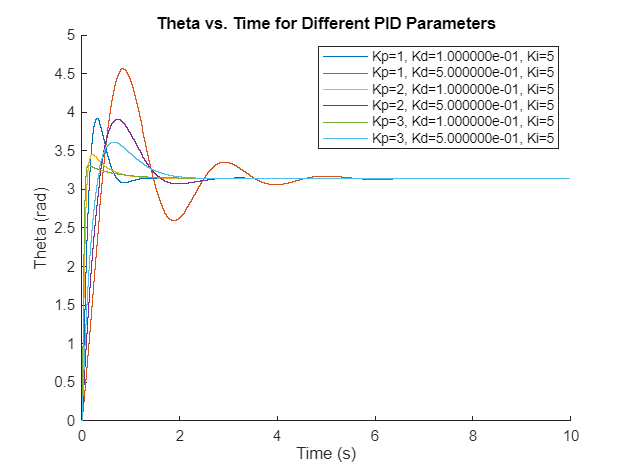


hold off;
title('Theta vs. Time for Different PID Parameters');
xlabel('Time (s)');
ylabel('Theta (rad)');
legend show;

# 3 - Feed Forward Neural Network (FFNN)

To introduce reservoir computing, it's important to first understand neural networks.

Neural networks process information through a series of weighted nodes, producing a desired output. 

One of the simplest types of neural networks is the feedforward neural network. 

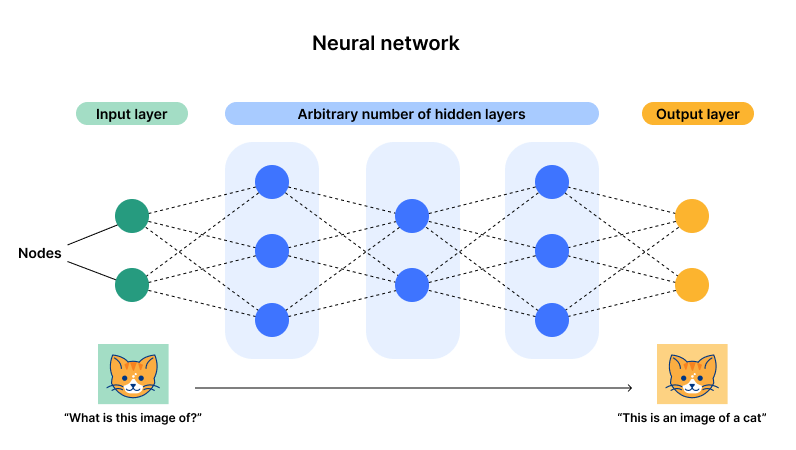

In a feedforward neural network, input data is fed into the first layer and then passes through a series of hidden layers where it is adjusted. 

The final output is read from the output layer. Essentially, data flows from the input (front) to the output (back).

**What is a node and how is it updated (Concept)**

The state of each node continually changes depending on the states of other nodes.

In an FFNN, the updated value of each node is given as a weighted sum of the values of the nodes in the previous layer plus some bias.

This sum is then passed through a non-linear activation function such as tanh(x) to give the new state of the node. 

Each node within the network reservoir can be expressed as a value, ${S_n }^l$, where $n$.represents the number of this node within it's respective layer and $l\;$represents layer.

                                                  
$${S_j }^{\left(l+1\right)} =\tanh \left(\sum_i {w_{\mathrm{ij}} }^{\left(l\right)} {S_i }^{\left(l\right)} \;\;+{b_j }^{\left(l+1\right)} \right)$$


This non-linear activation function allows for complex characteristics to be captured.

Without an activation function like tanh(), a multilayer neural network would essentially behave as a linear model, losing all complexity introduced by the multilayer architecture. 

             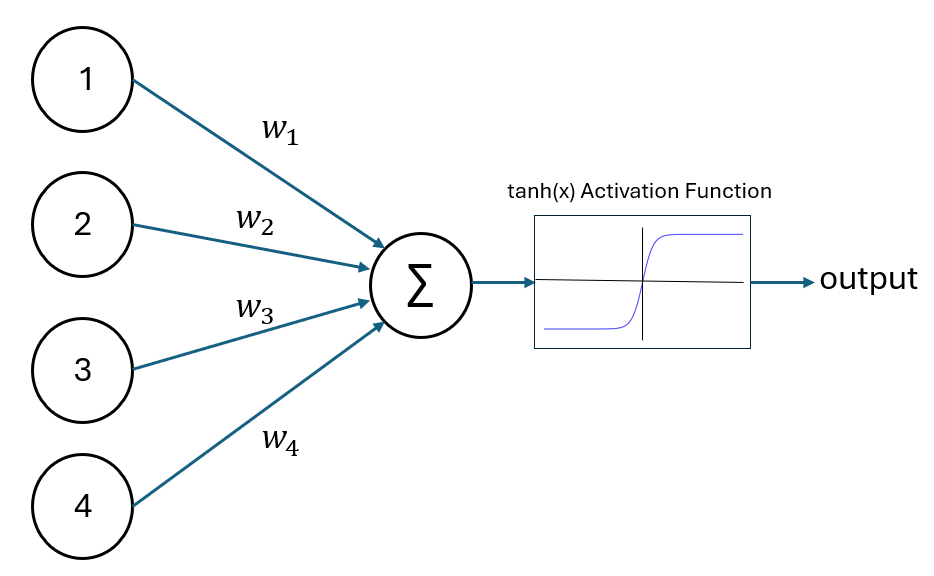

**tanh(x) activation function (delete code)**

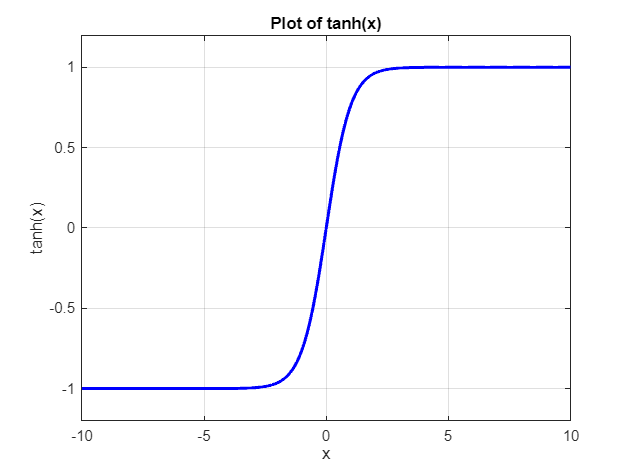

%%%%%%%%%%%%%% RUN TO PLOT TANH(X) FUNCTION %%%%%%%%%%%%%%
x = linspace(-10, 10, 1000);
y = tanh(x);

figure();
plot(x, y, 'b-', 'LineWidth', 2);
grid on;
title('Plot of tanh(x)');
xlabel('x');
ylabel('tanh(x)');

axis([-10 10 -1.2 1.2]); 

## FFNN - Deep Supervision 

In the feedforward neural network (FFNN) described above, data flows into the input layer and is read out from the output layer. 

An alternative approach is to input data into all the nodes and read outputs from all the nodes, a method known as deep supervision.

To demonstrate this principle with a simpler example, consider a neural network with just four nodes used to control a single pendulum

In our example we have four input states $\left(\theta ,\dot{\theta} ,\theta^* ,{\dot{\theta} }^* \right)$ these represent the pendulum's: angle, angular velocity, desired angle and desired angular velocity respectively. 

                                    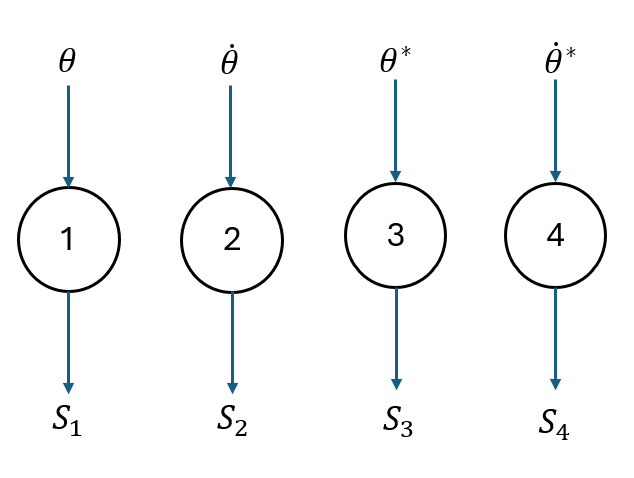

In this network, there is no explict input and output layer. The input parameters are continually fed into all nodes of our network and the readout is continually read from all attributes (states and input) of the network. 

**Characterisitic Equation of Reservoir.**

For this type of network we have a modifed characteristic equation caputing the layerless structure of our new network.

                                                
$$\dot{S} = -S + \tanh(W_{\text{in}} \cdot u + W_r \cdot S + W_b)
$$


where: 

- $u$ is the input matrix from the robot, $\left(\theta ,\dot{\theta} ,\theta^* ,{\dot{\theta} }^* \right)$in this case

- $S$is the current state of the reservoir 

- $W_{\textrm{in}} \;$is the input matrix which transforms the robot's dimensions into the higher dimensions of the reservoir 

- $W_r$ is the reservoir matrix.

- $W_b$ is the bias matrix.

**How are the nodes connected**

Keeping the FFNN approach from before we can set the nodes up to behave in a similar manner to the FFNN where data flows in a forward direction through the layers.

                         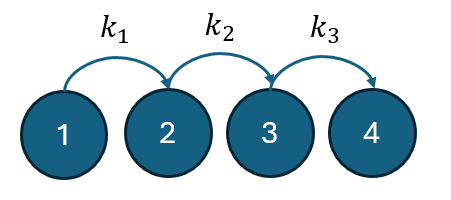

  
$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;W_r =\;\left\lbrack \begin{array}{cccc}
0 & 0 & 0 & 0\\
k_1  & 0 & 0 & 0\\
0 & k_2  & 0 & 0\\
0 & 0 & k_3  & 0
\end{array}\right\rbrack$$


The relationships between the nodes can be represented using different values of k, which can be organized within a transition state matrix.,$W_r$.

**Generating an output**

For our single pendulum example we want one single output, the applied torque.

                                            
$$\tau =\;\left\lbrack \begin{array}{c}
b\\
\dot{\theta} \\
\dot{\theta} \\
\theta^* \\
{\dot{\theta} }^* \\
S_1 \\
\ldotp \ldotp \ldotp \\
S_N 
\end{array}\right\rbrack \left\lbrack \begin{array}{cccccccc}
w_{\mathrm{out}1}  & w_{\mathrm{out2}}  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & w_{\mathrm{out}\;N-1}  & w_{\mathrm{outN}} 
\end{array}\right\rbrack$$


This can be calculated as a weighted sum of the all the current states and the current state of the robot. 

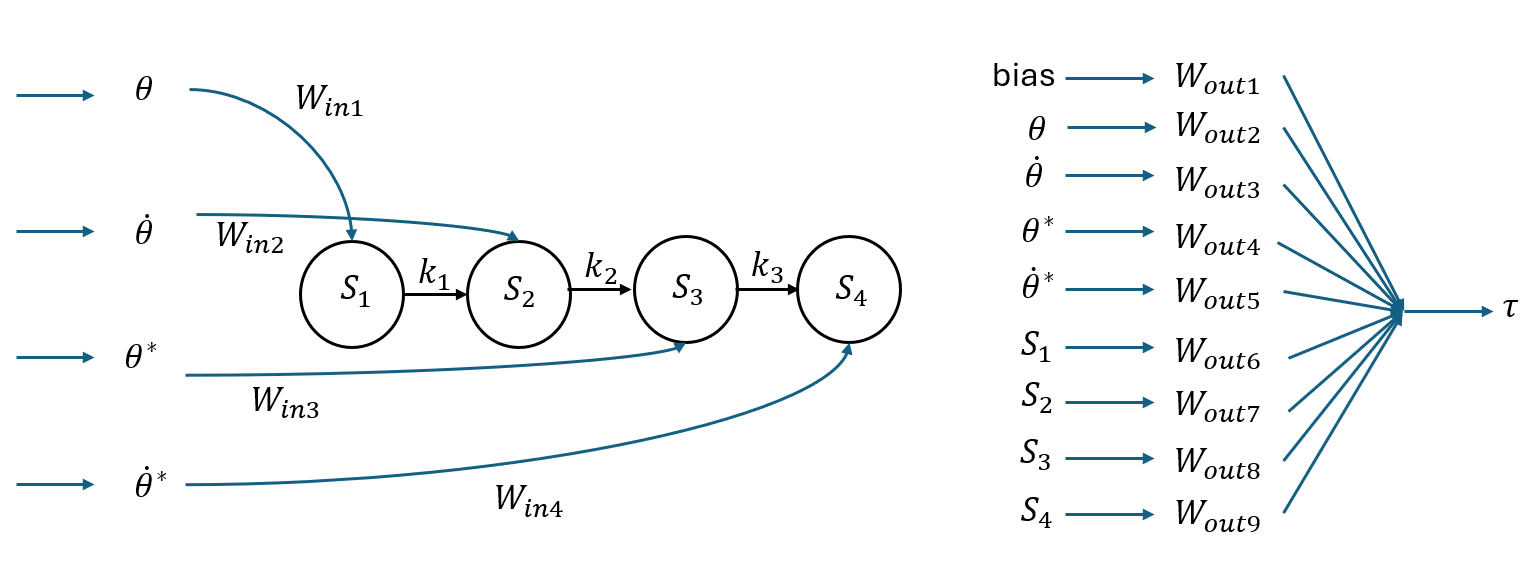

**FFNN Control Applied to Pendulum**

In order to control a pendulum, these weights can be optimised to reduce the mean squared error.

For a four node network there is a total of 16 variables. 

- 3 interconnection weights - $k_{1,} \;k_2 \;\textrm{and}\;k_3$

- 4 input weights - $W_{\mathrm{in}\;} =\left\lbrack w_{\mathrm{in}1} ,w_{\mathrm{in}2} ,\;w_{\mathrm{in}3,} \;w_{\mathrm{in}4} \right\rbrack$

- 9 output weights - $W_{\mathrm{out}\;\;} =\left\lbrack w_{\mathrm{out1},} ,w_{\mathrm{out2}} ,w_{\mathrm{out3}} ,w_{\mathrm{out4},\;} ,w_{\mathrm{out5}} ,w_{\mathrm{out6}} ,w_{\mathrm{out7}} ,w_{\mathrm{out8},} ,w_{\mathrm{out9}} \right\rbrack$

The relationship betweeen the values of the states, the input values, and the desired output can be complex and computationally expensive.

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% RUN TO TEST FFNN FOR PENDULUM CONTROL %%%%%%%%%%%%%%%%%%%

Nr = 4; %this is the number of nodes within the reservoir 
sizeinput = 4; %theta, thetadot, theta*, thetadot*
sizeoutput = 1; %only output from the reservoir is the control torque.
iscontrol = false; %true is the pendulum is controlled by reservoir, false is pendulum is not controlled (free fall) 

modelname = "Pendulum_network_control";

reservoir_type = "FFNN";

rc = trainbysim(Nr, 'reservoir_type', reservoir_type, 'sizeinput', sizeinput, 'nodenuminput', 3, 'sizeoutput', sizeoutput, ...
    'timeConst', timeConstant, 'spectralRadius', SR, 'inputScaling', 1, 'connectivity', 1, 'biasScaling', 0, ...
    'regularization', 1e-1, 'delaylen', 0.1, 'timestep', 0.01, 'normmethod', normmethod, 'ifxnorm', ifxnorm);    

[SinusoidBus, busin] = create_bus_input(control_ref, dt);  %this is used later to set the desired theta and thetadot, it is not used during training 

rc.clearrecord(); 

%%%%%%%%%%%%%%%%%%%%%%%%%% FINE TUNED PARAMETERS  %%%%%%%%%%%%%%%%%%%%%%%

% Define initial values for rc.Wr, rc.Win, and rc.Woutmat
rc.Wr = [
    0, 0, 0, 0;
    0.2449, 0, 0, 0;
    0, 0.6409, 0, 0;
    0, 0, 0.3845, 0
];
rc.Win = [0.3985; 0.6250; 0.5676; 0.8945];
rc.Woutmat = [0.2530, -4.2472, -0.2995, 4.3397, -0.1214, -1.3510, 0.1540, -0.1382, -0.0018];

%%%%%%%%%%%%%%%%%%%%%%%%%% FINE TUNED PARAMETERS  %%%%%%%%%%%%%%%%%%%%%%%


%%%%%%%%%%%%%%% SET CONTROL PARAMETERS  %%%%%%%%%%%%%
iscontrol = true;
robot_ini_theta_p = 0;
robot_ini_thetadot_p = 0;
control_ref = [pi; 0];
stoptime = 10;
[SinusoidBus, busin] = create_bus_input(control_ref, dt);

controloutput = rc.robotcontrol(modelname, simTime);

theta_error = control_ref(1) - controloutput(2,end)

theta_error = 0.1226

thetadot_error = control_ref(2) - controloutput(3,end) %(add graph)

thetadot_error = -2.1675e-14

%%%%%%%$%%%% THE ABOVE FFNN HAS A NOTICABLE ERROR FROM PI %%%%%%%%%%%%

%%%%%%%%%%% TRY CHANGING THE WEIGHTS TO SEE IF YOU CAN FIX IT %%%%%%%%%%%

%%%%%%% TO RESET TO FINE TUNED VALUES RIGHT CLICK THE SLIDERS %%%%%%%% 


%%%%%%%% TUNING INTERCONNECTIONS %%%%%%%%
k_1 =0.2449;
k_2 = 0.6409;
k_3  =0.3845;


%%%%%% TUNING INPUT WEIGHTS %%%%%%%%%%%%
w_in1 = 0.3985;
w_in2 =0.625;
w_in3 = 0.5676;
w_in4 =0.8945;


%%%%%%%% TUNING OUTPUT WEIGHTS %%%%%%%%%
w_out1 = 0.253;
w_out2 =-4.2472;
w_out3 = -0.2995;
w_out4 =4.3397;
w_out5 = -0.1214;
w_out6 =-1.351;
w_out7 = 0.154;
w_out8 =-0.1382;
w_out9 = -0.0018;

**Update Neural Network**

%%%%%%%%%% UPDATE AND DISPLAY NEW WEIGHTS %%%%%%%%%%%
update_weights()

rc.Wr %(k_1, k_2, k_3)

ans =          0         0         0         0
    0.2449         0         0         0
         0    0.6409         0         0
         0         0    0.3845         0


rc.Win %(W_in1, W_in2, W_in3, W_in4)

ans =     0.3985
    0.6250
    0.5676
    0.8945


rc.Woutmat %(W_out1, W_out2, W_out3, W_out4, W_out5, W_out6, W_out7, W_out8, W_out9)

ans =     0.2530   -4.2472   -0.2995    4.3397   -0.1214   -1.3510    0.1540   -0.1382   -0.0018


**Test Control Performance**

%%%%% YOU WILL NOTICE OPTIMISING THE WEIGHTS IS DIFFUCULT %%%%%%%%%


%%%%%%%%%%%%%%% SET CONTROL PARAMETERS  %%%%%%%%%%%%%
iscontrol = true;
robot_ini_theta_p = 0;
robot_ini_thetadot_p = 0;
control_ref = [pi; 0];
stoptime = 10;
[SinusoidBus, busin] = create_bus_input(control_ref, dt);

controloutput = rc.robotcontrol(modelname, simTime);
theta_error = control_ref(1) - controloutput(2,end)

theta_error = 0.1226

thetadot_error = control_ref(2) - controloutput(3,end) 

thetadot_error = -2.1675e-14

The process of hand tuning is clearly long and inefficient, it may take thousands of iterations to achieve perfect control. 

The process of finding optimal weights can be automated using backproperagation.

This process involves running thousands of simulations and using gradient descent to find the optimal weight parameters.

# **4 - Reservoir Computing**

This process of backpropagation and optimization can be computationally expensive for larger, more complex models.

 In contrast, reservoir computing offers the abiltiy to significantly reduce the computational complexity of training a model, lowering the required training samples from potentially thousands to just two.

Unlike traditional methods such as backpropagation and optimization, reservoir computing divides training into two distinct stages:

- Fixing the input and interconnection weights.

- Training the output weights.

This two-stage design process creates a linear relationship between the reservoir states and the desired output. Due to this linearity, we can utilize quick and efficient training methods, such as linear regression, which dramatically reduce training time and the number of required samples.

Traditional optimization and backpropagation methods do not train on data that have linear relationships, and hence, fast linear methods cannot be used with them.

**What is a reservoir?**

A reservoir consists of a network of interconnected nodes that can represent the non-linear components of a system. 

The concept is that the reservoir can model the inverse dynamics of the robot, thereby enabling effective control of the robot.

A reservoir has three main stages:

- **Input**: This layer typically maps lower-dimensional input variables into the higher-dimensional space of the reservoir.

- **Reservoir**: A collection of nodes connected by assigned weights.

- **Output**: A trained layer that reads from the state of the reservoir and input variables to produce a lower-dimensional output.

A set of readout weights can be trained to read from the state of the reservoir to achieve a desired value or target.

                                                           
$$W^{\text{OUT}} = (S'S)^{-1}S'\tau
$$


               
$$W_{\textrm{OUT}} =\;{\left\lbrack \begin{array}{c}
W_5 \\
W_6 \\
\ldotp \ldotp \ldotp \\
W_{N+6} 
\end{array}\right\rbrack }_{\textrm{Nx1}}$$
   
$$S={\left\lbrack \begin{array}{cccc}
S_{1,1}  & S_{1,2}  & \ldotp \ldotp \ldotp  & S_{1,T} \\
S_{2,1}  & S_{2,1}  & \ldotp \ldotp \ldotp  & S_{2,T} \\
\ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp  & \ldotp \ldotp \ldotp \\
S_{N,1}  & S_{N,2}  & \ldotp \ldotp \ldotp  & S_{N,T} 
\end{array}\right\rbrack }_{\textrm{NxT}}$$
   
$$\tau ={\left\lbrack \begin{array}{c}
\tau_1 \\
\tau_2 \\
\ldotp \ldotp \ldotp \\
\tau_T 
\end{array}\right\rbrack }_{\textrm{Tx1}}$$


where:

- **N, **number of nodes in the reservoir.

- **T, **total number of timesteps in the training simulation. 

- $W_n$ are the readout weights 

- S is the state of a node 

- $\tau \;$is the target torque.

# **5 - Reservoirs Applied to Control **

Reservoirs can be used to simulate the inverse dynamics of a robot and hence used to control the movement of that robot. 

To use a reservoir for control, a reservoir must first be defined. We will continue to use the FFNN connection style.

The reservoir is created as a class of name "trainbysim".

%%%%%%%%%%%%%%%%%%%%%%% CREATING A RESERVOIR %%%%%%%%%%%%%%%%%%%%%%%%

Nr = 4; %this is the number of nodes within the reservoir 
sizeinput = 4; %theta, thetadot, theta*, thetadot*
sizeoutput = 1; %only output from the reservoir is the control torque
iscontrol = false; %true is the pendulum is controlled by reservoir, false is pendulum is not controlled (free fall) 

modelname = "Pendulum_network_control";

reservoir_type = "FFNN";

rc = trainbysim(Nr, 'reservoir_type', reservoir_type, 'sizeinput', sizeinput, 'nodenuminput', 3, 'sizeoutput', sizeoutput, ...
    'timeConst', timeConstant, 'spectralRadius', SR, 'inputScaling', 1, 'connectivity', 1, 'biasScaling', 0, ...
    'regularization', 1e-1, 'delaylen', 0.1, 'timestep', 0.01, 'normmethod', normmethod, 'ifxnorm', ifxnorm);     %the initilisation parameter


%%%%%%%%%% IMPLEMENTATIONB OF FFNN INTO RESERVOIR %%%%%%%%%%
rc.Wr  = [
    0, 0, 0, 0;
    0.2449, 0, 0, 0;
    0, 0.6409, 0, 0;
    0, 0, 0.3845, 0
];  %FFNN connections from above 


[SinusoidBus, busin] = create_bus_input(control_ref, dt);  %this is later used to set the desired theta and thetadot, it is not used during training. 

**How to train? **

To train the reservoir to control the pendulum, the pendulum can simply be dropped from a location close to the top.

The dropping is equivalent to it exploring the state space of the environment 

This results in charactistics plots for torque, angle and angular velocity.

%%%%%%%%%%%% RUN TO SHOW THE STATE SPACE EXPLORED DURING TRAINING %%%%%%%%%%%%

PID_on = false; % PID_on as false means the pendulum drops freely, PID_on as true means PID controller tries to control to desired angle
desired_theta = pi;  % the desired angle of the pendulum when using PID controller

robot_ini_theta_p = pi+0.1;
robot_ini_thetadot_p = 0;
dt = 0.01;

out_simulation = sim("PID_pendulum");

theta = out_simulation.yout{1}.Values.theta;
theta_dot = out_simulation.yout{1}.Values.thetadot;
torque = out_simulation.yout{1}.Values.totaltorque;

% Create a wider figure
ff = figure();
ff.Position = [100, 100, 1200, 400];
% figure();

% Plot theta
subplot(1, 3, 1); % 1 row, 3 columns, first subplot
plot(theta.Time, theta.Data);
title('Theta');
xlabel('Time (s)');
ylabel('Theta (rad)');

% Plot theta_dot
subplot(1, 3, 2); % 1 row, 3 columns, second subplot
plot(theta_dot.Time, theta_dot.Data);
title('Theta Dot');
xlabel('Time (s)');
ylabel('Theta Dot (rad/s)');

% Plot torque
subplot(1, 3, 3); % 1 row, 3 columns, third subplot
plot(torque.Time, torque.Data);
title('Torque');
xlabel('Time (s)');
ylabel('Torque (Nm)');

% Adjust layout
sgtitle('Simulation Results');

**Training Process **

There are three functions that need to be called in order to train the reservoir

- **Traintest - **Normalises the inputs so each varaible is equally as significant.

- **Traindatacollect - **Drops the pendulum and collects the state values, $\theta ,\dot{\theta} ,\theta^* ,{\dot{\theta} }^* \;$and $\ddot{\theta}$ (analoglous to torque). 

- **Train - **Calculates the weights based on the collected data using linear regression.

The * within the state of the robot represents the target angle or angular velocity. During control this is generally fixed value such as ($\pi$, 0) however during training this takes on the future state of the robot. 

By inputting the data to the reservoir at a delay, the reservoir is able to see the current state of the robot as well as the future state.

This process learns to map reservoir and robot states to real world torques using the calculated weights.

                        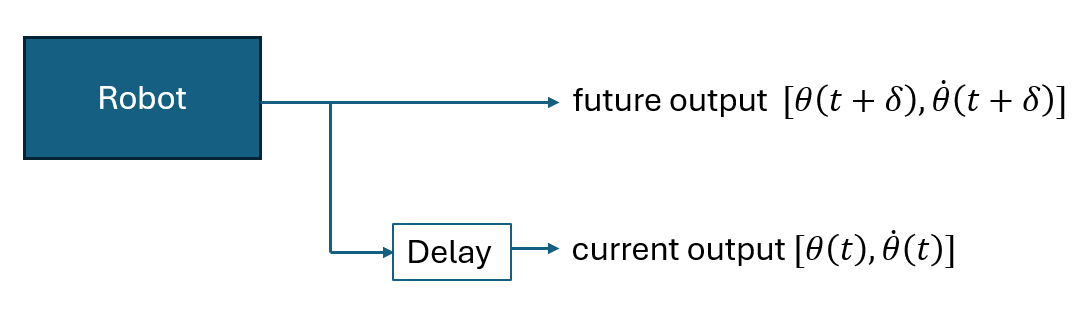

%%%%%% RUN TRAINING PROCESS %%%%%%%

rc.clearrecord();
rc.traintest(modelname, simTime);

rc.traindatacollect(modelname, washout, simTime);
rc.train();

Size of X
     9   941

Size of Y 
   941     1

These are the weights
    0.0605   -3.4547   -0.2548    3.4570   -0.0725    0.0177   -0.0832    0.0071   -0.1582



When the robot needs to be controlled, the control torque can be read as a combination of the current reservoir states and the parameters of the robot.

This time the * represents the desired state of the robot. For example to balance on the top of the joint the $\left(\theta^* ,\dot{\theta^* } \right)=\left(\pi ,0\right)$.

**Using the reservoir for control **

%%%%%% RUN TO TEST THE CONTOL PERFORMANCE OF RESERVOIR %%%%%%%%%%%


%%%%%%%%%%%%%%% SET CONTROL PARAMETERS  %%%%%%%%%%%%%
iscontrol = true;
robot_ini_theta_p = 0;
robot_ini_thetadot_p = 0;
control_ref = [pi; 0];
[SinusoidBus, busin] = create_bus_input(control_ref, dt);


%%%%%%%%%%%%%%%%% SHOW ERROR %%%%%%%%%%%%%%%%%%%
controloutput = rc.robotcontrol(modelname, simTime);
theta_error = control_ref(1) - controloutput(2,end)

theta_error = 0.0076

thetadot_error = control_ref(2) - controloutput(3,end)

thetadot_error = -1.5274e-14

Depending on the reservoir used you may or may not be be able to balance the pendulum and so reservoir computing contains some degree of luck. 

"Good" reservoirs should have theta errors < 0.05 whereas "bad" reservoirs may not be able to control the pendulum at all.

**Changing the reserovir connections**

While the FFNN replica works for this case, it is only able to capture simple dynamics.

 By populating the reservoir with more connections, including recurrent ones, the reservoir is still able to control the pendulum while also holding potential for capturing more complex dynamics.

The simplest approach is to randomly populate a reservoir. While this can be effective in certain scenarios, relying on luck can be detrimental, especially when dealing with larger, more complex systems.

Try using a tuned FFNN reservoir and compare the control performance to a randomly generated reservoir

**Visualisation of Interconnectivity**

                    
$$\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;\;W_r =\;\left\lbrack \begin{array}{cccc}
W_{\left(1,1\right)}  & W_{\left(1,2\right)}  & W_{\left(1,3\right)}  & W_{\left(1,4\right)} \\
W_{\left(2,1\right)}  & W_{\left(2,2\right)}  & W_{\left(2,3\right)}  & W_{\left(2,4\right)} \\
W_{\left(3,1\right)}  & W_{\left(3,1\right)}  & W_{\left(3,3\right)}  & W_{\left(3,4\right)} \\
W_{\left(4,1\right)}  & W_{\left(4,1\right)}  & W_{\left(4,3\right)}  & W_{\left(4,4\right)} 
\end{array}\right\rbrack$$


                           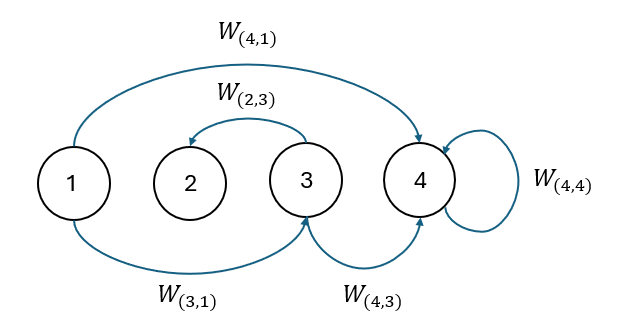

**Changing the FFNN Reservoir**

%%%%%%%% TUNE THE FFNN RESERVOIR PARAMETERS %%%%%%%%
k_1 =0.2449;
k_2 = 0.6409;
k_3  =0.3845;

update_weights();  
Wr = rc.Wr; %move to new variable so it can be remembered after new reservoir generation

**Generating a Random Reservoir**

%%%%%%% RUN FOR RANDOM RESERVOIR %%%%%%%%

NodeNum = 4;   %Number of nodes within the reservoir    Use 
Connectivity = 0.5; %Density of connections, e.g. 0.5 is 50% of elements are non zero
Wr = full(sprand(NodeNum, NodeNum, Connectivity))

Wr =     0.5523         0         0         0
         0         0    0.9791    0.5493
         0    0.3304    0.6195         0
         0    0.3606    0.7565    0.4139


**Visualisation of Wr **

%%%%% RUN TO SHOW EXAMPLE OF NDOE CONNECTIONS %%%%%

p = abs(Wr);
[m, n] = find(p~=0);
v = [];
for i = 1:size(m,1)
    v(i) = Wr(m(i),n(i));
end

Create a digraph
figure();
g = digraph(m, n, v);
pp = plot(g);

Ensure all nodes are in a horizontal line
numNodes = max(max(m), max(n)); % Find the maximum node index
pp.XData = 1:numNodes; % Set XData to sequential integers
pp.YData = zeros(1, numNodes); % Set YData to zero

Increase node size
pp.MarkerSize = 50; % Adjust this value to make nodes larger or smaller

Add custom node labels to ensure they are centered
pp.NodeLabel = {}; % Remove default node labels
for i = 1:numNodes
    text(pp.XData(i), pp.YData(i), num2str(i), ...
        'HorizontalAlignment', 'center', 'VerticalAlignment', 'middle', ...
        'FontSize', 12, 'FontWeight', 'bold', 'Color', 'black');
end

axis off;
pp.EdgeCData = v;
pp.ArrowSize = 10;
pp.LineWidth = 3.0;


Add colorbar
cb = colorbar();

Size of X
     9   941

Size of Y 
   941     1

These are the weights
    0.0558   -3.7928   -0.2727    3.7906   -0.0935   -0.1277    0.0869   -0.3812    0.2803



cb.Limits = [-1 1];
cb.Ticks = [-1 0 1];
colormap(flipud(othercolor('RdBu5')));
cb.Position = [0.85, 0.15, 0.025, 0.7]; % below show

**Train Using New Reservoir**

%%%%%%%%%%%%%%%TRAIN OUTPUT WEIGHTS %%%%%%%%%%%%%


Nr = 4;
sizeinput = 4;
sizeoutput = 1;
timeConstant = 1;
define_variables;
reservoir_type = "FFNN";

theta_error = -0.0075

modelname = "Pendulum_network_control";
% 
% 
rc = trainbysim(Nr, 'reservoir_type', reservoir_type, 'sizeinput', sizeinput, 'nodenuminput', 3, 'sizeoutput', sizeoutput, ...
    'timeConst', timeConstant, 'spectralRadius', SR, 'inputScaling', 1, 'connectivity', 1, 'biasScaling', 0, ...
    'regularization', 1e-1, 'delaylen', 0.1, 'timestep', 0.01, 'normmethod', normmethod, 'ifxnorm', ifxnorm);     %the initilisation parameter

rc.Wr = Wr;


PID_on = false; % PID_on as false means the pendulum drops freely, PID_on as true means PID controller tries to control to desired angle
desired_theta = pi;  % the desired angle of the pendulum when using PID controller

%rc.Wr = Wr
robot_ini_theta_p = pi+0.1;
robot_ini_thetadot_p = 0;
dt = 0.01;

iscontrol = false;
robot_ini_theta_p = pi+0.1;
robot_ini_thetadot_p = 0;

[SinusoidBus, busin] = create_bus_input(control_ref, dt);


rc.clearrecord();
rc.traintest(modelname, simTime);
rc.traindatacollect(modelname, washout, simTime);
rc.train();

**Control Using New Reservoir**


%%%%%%%%%%%%% SET CONTROL PARAMETERS %%%%%%%%%%%%%
iscontrol = true;
robot_ini_theta_p = 0;
robot_ini_thetadot_p = 0;
control_ref = [pi; 0];
stoptime = 100;
[SinusoidBus, busin] = create_bus_input(control_ref, dt);

%%%%%%%%%%%%%%%%% SHOW ERROR %%%%%%%%%%%%%%%%%%%
controloutput = rc.robotcontrol(modelname, simTime);
theta_error = control_ref(1) - controloutput(2,end)

**Echo State Network Reservoir (extension)**

An Echo State Network is a form of reservoir where:

- Influence of input to the reservoir state diminish over time (Echo State Property)

The echo state property ensures that the internal state of the reservoir asymptotically depends only on the input history and not on the initial state of the network. 

This means that after a sufficiently long input sequence, the influence of the initial conditions (the initial state of the neurons in the reservoir) fades away, and the network's state is determined by the inputs it has received over time.

Ruccurent connections (unlike in the FFNN) within the reservoir can help to increase the chance of the Echo State Property being met. 

# **Conclusion:**

This tutorial aims to demonstrate and apply the idea of reservoir computing when used for control of a simple pendulum.

By splitting network creation into two distinct stages we are able to take advantage of the linear relationship between node states and the readout.

This linear relationship dramatically reduces the training time from traditional optimisation methods to just a couple of seconds.

**How can reservoir be taken further...**

**Control of More Complex Systems**

The current fully actuated case is simple, and the dynamics are straightforward, as shown by the fact that a linear controller can perform equally well. Theoretically, a reservoir should be able to emulate the inverse dynamics of any system regardless of complexity. To investigate how well the reservoir can model more complex systems, we can move to investigate the underactuated pendulum, where the reservoir must learn to resonate the pendulum in order to balance it.

**Optimizing Reservoir Design**

By optimizing different hyperparameters of the reservoir, we can achieve different control characteristics. Similar to how PID parameters affect control performance, we can investigate how to vary hyperparameters to achieve specific control characteristics.

**IMAGES FROM CODE (RESTART LIVE SCRIPT IF THEY DON'T SHOW IN THE CODE)**